hcData = load('Debye/Cp_final.txt');
T = hcData(:, 1);  % Temperature in K
C_exp = hcData(:, 2);      % Cp in J/Kmol per Gd5Pbb3 #8 atoms
%% Set Temperature Cutoff
T_cutoff = 300; % Change this value to set the maximum temperature for fitting

% Filter Data: Keep only points where T <= T_cutoff
valid_idx = T <= T_cutoff;
T = T(valid_idx);
C_exp = C_exp(valid_idx);

%constants
R = 8.314 % Gas constant (J/mol·K)

R = 8.3140

a = 8 %number of atoms

a = 8

debye_integral = @(x) (x.^4 .* exp(x)) ./ ((exp(x) - 1).^2);

% Function to compute specific heat for given T and parameters
function C_D = compute_debye_C(T, theta_D, debye_integral, R)
    % Numerical integration of Debye function
    integral_value = integral(@(x) debye_integral(x), 0, theta_D/T, 'ArrayValued', true);
    C_D = 9 * R * (T/theta_D)^3 * integral_value;
end

% Einstein specific heat function
function C_E = compute_einstein_C(T, theta_E, R)
    exp_term = exp(theta_E ./ T);
    C_E = 3 * R * (theta_E ./ T).^2 .* exp_term ./ (exp_term - 1).^2;
end

function C = compute_debye_einstein_C(T, theta_D, theta_E_1, theta_E_2, f_D, f_E, debye_integral, R, a)
    C_D = compute_debye_C(T, theta_D, debye_integral, R);
    C_E_1 = compute_einstein_C(T, theta_E_1, R);
    C_E_2 = compute_einstein_C(T, theta_E_2, R);
    C = a*(f_D * C_D + (1 - f_D) * C_E_1 + (f_E)*C_E_2); % Weighted sum of Debye and Einstein contributions
end

debye_einstein_model_scalar = @(theta_D, theta_E_1, theta_E_2, f_D, f_E, T) arrayfun(@(t) compute_debye_einstein_C(t, theta_D, theta_E_1, theta_E_2, f_D, f_E, debye_integral, R, a), T);
% Define custom fit type
fit_type = fittype(@(theta_D, theta_E_1, theta_E_2, f_D, f_E, T) debye_einstein_model_scalar(theta_D, theta_E_1, theta_E_2, f_D, f_E, T), ...
    'independent', 'T', 'coefficients', {'theta_D', 'theta_E_1', 'theta_E_2', 'f_D', 'f_E'});

% Initial guesses
theta_D_guess = 300; % Initial guess for theta_D0
theta_E1_guess = 1000;
theta_E2_guess = 1000;
f_D_guess = 0.5;
f_E_guess = 0.25;
% Fit model to data
fit_result = fit(T, C_exp, fit_type, 'StartPoint', [theta_D_guess, theta_E1_guess, theta_E2_guess, f_D_guess, f_E_guess], ...
                         'Lower', [0, 0,0,0, 0], ... % Lower bounds
                         'Upper', [1000,3000, 3000, 1, 1]);  % Upper bounds
% Extract fitted parameters
theta_D_fitted = fit_result.theta_D;
theta_E1_fitted = fit_result.theta_E_1;
theta_E2_fitted = fit_result.theta_E_2;
f_D_fitted = fit_result.f_D;
f_E_fitted = fit_result.f_E;

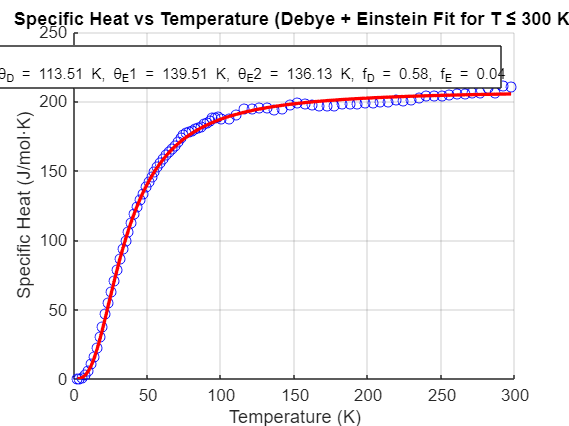

figure;
scatter(T, C_exp, 'bo', 'DisplayName', 'Filtered Data'); hold on;
plot(T, feval(fit_result, T), 'r-', 'LineWidth', 2, 'DisplayName', ...
    sprintf('Debye + Einstein Fit: θ_D = %.2f K, θ_E1 = %.2f K, θ_E2 = %.2f K, f_D = %.2f, f_E = %.2f', theta_D_fitted, theta_E1_fitted, theta_E2_fitted, f_D_fitted, f_E_fitted));
xlabel('Temperature (K)');
ylabel('Specific Heat (J/mol·K)');
title(sprintf('Specific Heat vs Temperature (Debye + Einstein Fit for T ≤ %d K)', T_cutoff));
legend;
grid on;

%% Export Fitting Results to a TXT File
output_file = 'fitting_results_debye_Einstein.txt';  % Name of the output file

% Extract fitted specific heat values
C_fitted = feval(fit_result, T); % Evaluate the fitted model at given temperatures

% Create a matrix with Temperature and Fitted Specific Heat
export_data = [T, C_fitted];

% Save the data to a text file
writematrix(export_data, output_file, 'Delimiter', 'tab');


disp(['Fitting results exported to ', output_file]);

Fitting results exported to fitting_results_debye_Einstein.txt
